# Monopolistic Firm Price Choice - Chapter 7 & 8: Interactive Visualization

This interactive visualization illustrates the price choice of a monopolistic firm, as explained in chapter 7, "The firm and its customers" of the book *The Economy*, The CORE Econ Team, Open access: [https://www.core-econ.org/the-economy/v1/book/text/07.html.](https://www.core-econ.org/the-economy/v1/book/text/07.html.) The case of a price-taking firm in a competitive market (chapter 8, "Supply and demand: Price-taking and competitive markets" is included as the particular case in which the demand curve is flat (that is price is constant).

A quadratic cost function $C\left(Q\right)=c_0 +c_1 Q+c_2 Q^2$ and a linear demand function $P\left(Q\right)=d_0 +d_1 Q$ are assumed, where *P* is the price and *Q* the quantity of product produced by the firm. To change the coefficients of the cost and demand function, as well as the axis limit, use the appropriate slider. As a result, the plot updates the shape of the functions (including the marginal, average and total cost curves), and the location of the solution (the chosen price and quantity). Displayed quantities like the equilibrium price and quantity, the consumer and producer surpluses, and the deadweight loss, are also updated.

## Display Curves

Cost function parameters.

c0 =1;
c1 =0.6;
c2 =0.4;

Demand function parameters.

d0 =2;
d1 =1;

Axes limits.

axl =3;

Plot functions.

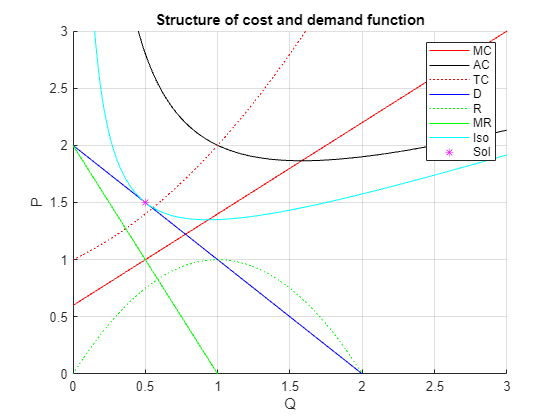

% define symbolic variables
syms P Q

% assumptions
assume([P Q]>0)

% define cost
C(Q) = c0 + c1*Q + c2*Q^2;

% define marginal cost
MC(Q) = diff(C(Q));

% clear and initialize existing figure
clf
xlabel('Q');ylabel('P');grid;
hold on

% plot marginal and average cost
fplot(MC(Q),3*[0 axl],'r');
fplot(C(Q)/Q,3*[0 axl],'k');

% plot total cost
fplot(C(Q),3*[0 axl],'r:');

% profit
V(Q,P) = P*Q - C(Q);

% plot profit isocurves
%fcontour(V,[0 axl 0 axl],':c');
title('Structure of cost and demand function');

% adjust axes limits
axis([0 axl 0 axl])

% define demand
P(Q) = d0 - d1*Q;

% plot demand
fplot(P(Q),[0 axl],'b');

% plot revenue and marginal revenue
fplot(P(Q)*Q,[0 axl],'g:');
fplot(diff(P(Q)*Q),[0 axl],'g');

% find optimal point
Qs = solve(diff(subs(V)));


% plot isoprofit curve at optimal point
legend(AutoUpdate="off")
fplot(C(Q)/Q + V(Qs,P(Qs))/Q ,[0 axl],'c');

% plot optimal point
plot(Qs,P(Qs),'*m'); 

% legend
legend('MC','AC','TC','D','R','MR','Iso','Sol')
hold off

In the figure, the (total) cost function is displayed with red dots (indicated with **TC** in the legend), and the demand function is displayed with a blue line (**D** in the legend). The marginal cost is defined as the derivative of the cost function with respect to quantity, and it is displayed with a red line and indicated with **MC** in the legend. The average cost function is defined as the cost divided by quantity, it is displayed with a black line, and indicated with **AC** in the legend. For more information on how these variables are calculated, look at the code by pressing the **Output inline** or **Output on right** buttons on the right hand side of the editor window.

The MC curve always intersects the AC curve at its minimum point. You can verify this by setting the derivative of the average cost equal to zero (the condition verified at the minimum point) and multiplying by *Q*. Intuitively, this happens because when MC (which is the cost of producing one more unit) is lower than the average cost, then producing one more unit is going to bring the average cost down. Conversely when MC>AC, producing one more unit is going to increase AC. When MC=AC, producing one more unit does not change the average cost. More generally, you can similarly prove that the marginal cost curve intersects the minimum of all isoprofit curves (the AC curve being the particular isoprofit curve when profit is zero).

The revenue is defined as price multiplied by quantity, it is displayed in dotted green, and indicated with **R** on the legend. The marginal revenue is defined as the derivative of the revenue with respect to quantity, it is displayed in green and indicated with **MR** on the legend.

The firm chooses the price and quantity to maximize profit, defined as revenue minus cost. The chosen price and quantity, that is the solution point, is displayed with a purple asterisk and indicated with **Sol** in the legend. Note that the quantity at the solution point is the one for which the marginal cost equals the marginal revenue (you can easily verify this by setting the derivative of the profit to zero, the maximum profit condition). The price at the solution point is then obtained by substituting the chosen *Q* into the demand function. The particular isoprofit curve at the solution point, which is the one that is tangent to the demand curve, is displayed in light blue and indicated by **Iso** in the legend.

## Solution Characteristics

Produced quantity.

disp("Q* = " + double(Qs));

Q* = 0.5


Price per unit.

disp("P* = " + double(P(Qs)));

P* = 1.5


Profit (revenue minus costs).

disp("Profit = " + double(V(Qs,P(Qs))));

Profit = -0.65


The consumer surplus is the sum of the surpluses experienced by each buyer. The surplus or a single buyer is the difference between the buyer willingness to pay and the price she actually pays. Note that this is only meaningful when the willingness to pay is represented by the market demand function, therefore, it's not valid in the monopolistic case because the demand seen by the firm (which is flat) is different than the whole market demand (more on this in the next section).

if d1>0
    disp("Consumer surplus = " + ...
    double((P(0)-P(Qs))*Qs/2));
end

Consumer surplus = 0.125


The producer surplus is the sum of the surpluses associated with each unit sold. The surplus or a single unit is the difference between the price at which the unit was sold and its marginal cost.

disp("Producer surplus = " + ...
    double((P(Qs)-MC(Qs))*Qs  + (MC(Qs)-MC(0))*Qs/2));

Producer surplus = 0.35


The Pareto point is the produced quantity for which the marginal cost is equal to the price.

Qp=solve(MC-P);
disp("Pareto point = " + double(Qp));

Pareto point = 0.77778


The deadweight loss is an additional potential surplus that could be split between the producer and the consumer but is lost due to the fact that the firm cannot set different prices for identical units, and chooses the single price that maximizes its profit. It is defined by sum of the positive differences between the demanded price and the marginal cost of each *unsold* unit.

disp("Deadweight loss = " + ...
    double( (Qp-Qs)*(P(Qs)-P(Qp))/2 + (Qp-Qs)*(P(Qp)-MC(Qs))/2 ));

Deadweight loss = 0.069444


## Competitive market case

In a competitive market with many firms, each firm is forced to be a price taker because raising the price of its own product would cause consumers to switch to other firms that sell the similar product at the same (lower) market price. Since the firm cannot raise the price, the demand function it faces is flat, that is an horizontal line in which the price is always equal to the market price. You can represent this case by using the slider to set the `d1` coefficient to zero (note that the demand function faced by the firm is different than the demand function of the market as a whole). 

You can verify that in this case, the the marginal revenue coincides with the demand curve. This happens because independently on the quantity, the revenue derived from selling one more unit of product is the market price, which is fixed. Therefore the solution lies at the intersection between the marginal cost function and the demand function. In other words, the firm is forced to accept the market price and chooses to produce a quantity of product so that its marginal cost is equal to the price. As for the monopolistic case, the quantity of product is the one that maximizes the profit, this is the quantity for which the marginal cost equals the price. 

The consumer surplus is not calculated for the competitive market case because it requires the whole market demand function, not the demand function seen by the single firm. However, it is important to notice that, differently from the monopolistic market case, there is no deadweight loss, because the marginal cost of each unsold units would be greater than its price. In other words, since the demand is flat, the solution is exactly at the Pareto point, and it is therefore called a Pareto-efficient solution.